Case Study 3: Conjugate Gradient Algorithm

Name: Marc Lane

Student ID: 21364269

Email: lanem2@tcd.ie

**Question 1:**

I implemented the CG algorithm section 6.7 of Saad’s textbook in the .m file "conjugate_gradient.m". It takes the matrix , the right-hand side vector , the tolerance (), and the maximum number of iterations () as arguments.

**Question 2:**

%% Parameters
tau = 20;
noise = 0.005;
tol = 1e-8;
sizes = [512, 1024, 2048]; % matrix sizes to test

% Store results in cell arrays
x_results = cell(1, length(sizes));
iters_results = zeros(1, length(sizes));
res_histories = cell(1, length(sizes));

for idx = 1:length(sizes)
    N = sizes(idx);
    fprintf('For N = %d\n', N);
    [A, b] = get_covariance_matrix(N, tau, noise);
    [x, iters, res_history] = conjugate_gradient(A, b, tol);
    x_results{idx} = x;
    iters_results(idx) = iters;
    res_histories{idx} = res_history;
    fprintf('Final relative residual = %.2e\n\n', res_history(end));
end

For N = 512


CG converged in 404 iterations


Final relative residual = 3.22e-10



For N = 1024


CG converged in 632 iterations


Final relative residual = 2.33e-10



For N = 2048


CG converged in 852 iterations


Final relative residual = 2.01e-10



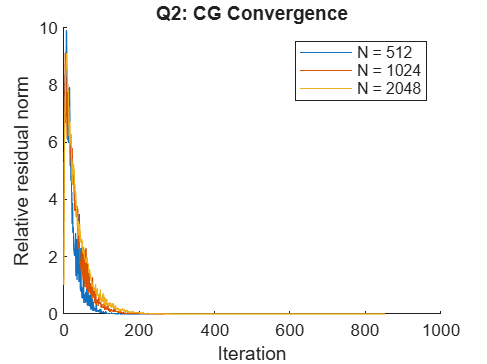


% Plotting relative residual norm vs iteration for each size
figure;
hold on;
for idx = 1:length(sizes)
    res = res_histories{idx};
    semilogy(0:length(res)-1, res, 'DisplayName', sprintf('N = %d', sizes(idx)));
end
xlabel('Iteration');
ylabel('Relative residual norm');
title('Q2: CG Convergence');
xlim([0, 1000]);
legend;
hold off;
saveas(gcf, 'Q2_convergence.png');

**    Question 3:**

%% Varying noise parameter
tau = 269;
tol = 1e-8;
N = 1024;

noise_values = [0.5, 5e-2, 5e-3, 5e-4, 5e-5, 5e-6, 5e-7, 5e-8];

for i = 1:length(noise_values)
    noise = noise_values(i);
    [A, b] = get_covariance_matrix(N, tau, noise);
    c = cond(A); % Computing the condition number of A
    fprintf('For Noise = %.1e, Condition number = %.2e\n', noise, c);
    [x, iters, res_history] = conjugate_gradient(A, b, tol);
    fprintf('\n');
end

For Noise = 5.0e-01, Condition number = 9.92e+02


CG converged in 35 iterations


For Noise = 5.0e-02, Condition number = 9.91e+03


CG converged in 73 iterations


For Noise = 5.0e-03, Condition number = 9.91e+04


CG converged in 166 iterations


For Noise = 5.0e-04, Condition number = 9.91e+05


CG converged in 438 iterations


For Noise = 5.0e-05, Condition number = 9.91e+06


CG did not converge: reached max iterations of (1000)


For Noise = 5.0e-06, Condition number = 9.87e+07


CG did not converge: reached max iterations of (1000)


For Noise = 5.0e-07, Condition number = 9.49e+08


CG did not converge: reached max iterations of (1000)


For Noise = 5.0e-08, Condition number = 6.85e+09


CG did not converge: reached max iterations of (1000)


The output shows that as the noise parameter decreases, the condition number of  A increases. This is likely because reducing the noise of A causes the eigenvalue spectrum to spread over a wider interval. CG is a Krylov subspace method that at each iteration constructs a polynomial of increasing degree that must be small at all eigenvalues of A simultaneously. When the eigenvalues are widely spread, higher-degree polynomials are needed to achieve this, requiring more iterations to converge.

From the results, each order of magnitude decrease in noise increases the condition number by about a factor of 10, and approximately doubles the number of iterations needed.

**Question 4:**

%% Generate A and b
[A, b] = get_covariance_matrix(1024, 100, 0.05);

% Run CG on original A
[x, iters, res_history] = conjugate_gradient(A, b, 1e-8);

CG converged in 131 iterations



% Compute A_new (Cholesky preconditioning)
L = chol(A, 'lower');        % lower triangular
M = L';                      % upper triangular
M_inv = inv(M);
A_new = M_inv * A * M_inv';

% Run CG on A_new
[x_new, iters_new, res_history_new] = conjugate_gradient(A_new, b, 1e-8);

CG converged in 13 iterations


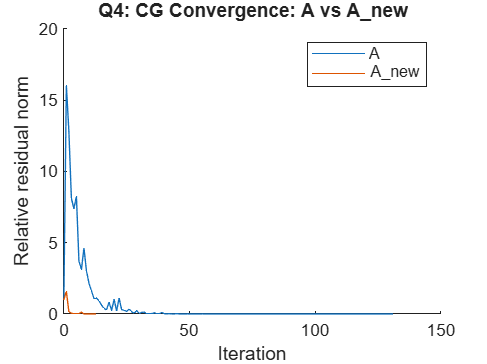


% Plot convergence
figure;
hold on;
semilogy(0:length(res_history)-1, res_history, 'DisplayName', 'A');
semilogy(0:length(res_history_new)-1, res_history_new, 'DisplayName', 'A\_new');
xlabel('Iteration');
ylabel('Relative residual norm');
title('Q4: CG Convergence: A vs A\_new');
legend;
hold off;
exportgraphics(gcf, 'Q4_A_vs_Anew.png', 'Resolution', 300);

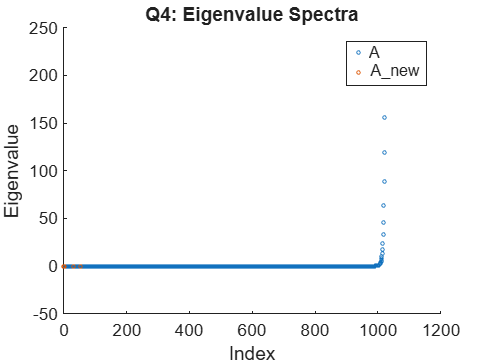


% Plot eigenvalue spectra
eigs_A = eig(A);
eigs_A_new = eig(A_new);

figure;
hold on;
semilogy(eigs_A, 'o', 'MarkerSize', 2, 'DisplayName', 'A');
semilogy(eigs_A_new, 'o', 'MarkerSize', 2, 'DisplayName', 'A\_new');
xlabel('Index');
ylabel('Eigenvalue');
title('Q4: Eigenvalue Spectra');
legend;
hold off;
exportgraphics(gcf, 'Q4_Eigenvalue_spectra.png', 'Resolution', 300);


fprintf('Condition number of A:     %.2e\n', cond(A));

Condition number of A:     4.40e+03


fprintf('Condition number of A_new: %.2e\n', cond(A_new));

Condition number of A_new: 4.58e+04


The eigenvalues of A are spread over a wider range, with most clustered near 10^-1 and suddenly increasing exponentially for higher indexes, giving a large condition number. Due to the Cholesky preconditioning, A_new's eigenvalues are much more tightly clustered, reducing the condition number significantly. CG constructs polynomials that must be small at all eigenvalues, so a tighter spectrum means a lower-degree polynomial suffices and convergence is faster. For this reason, A_new converges much faster than A.